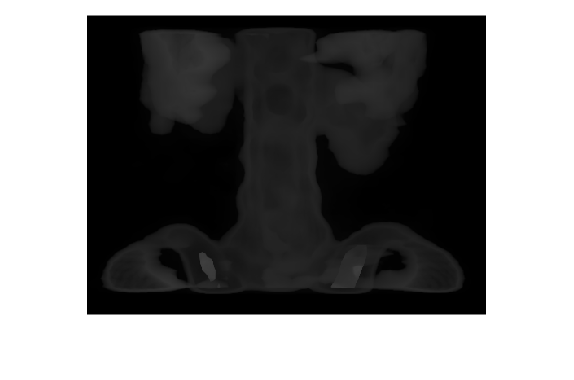

img = imread("spine.png");
imshow(img);

# Stretching the histogram : 

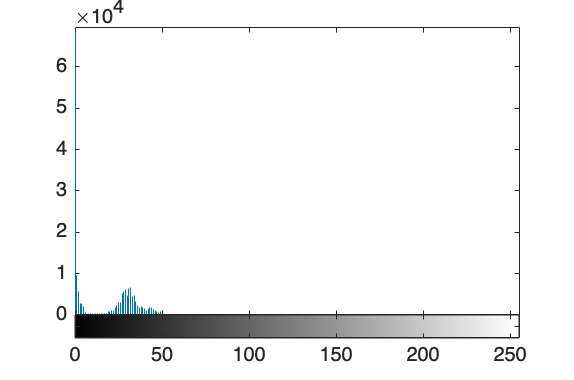

imhist(img);
ylim([0 Inf]);

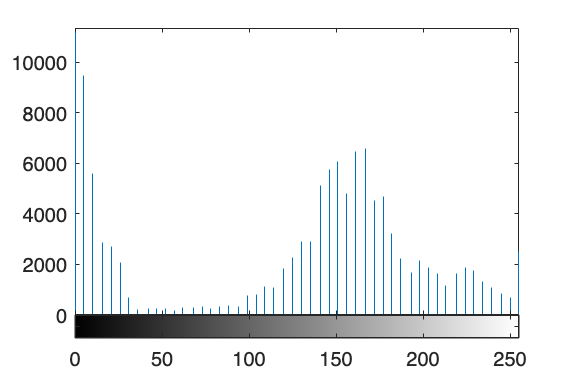


adj = imadjust(img);
imhist(adj);

# Montage of the adjusted vs original histogram : 

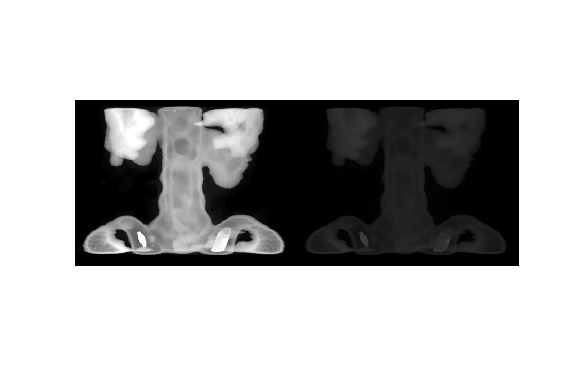

montage({adj,img})

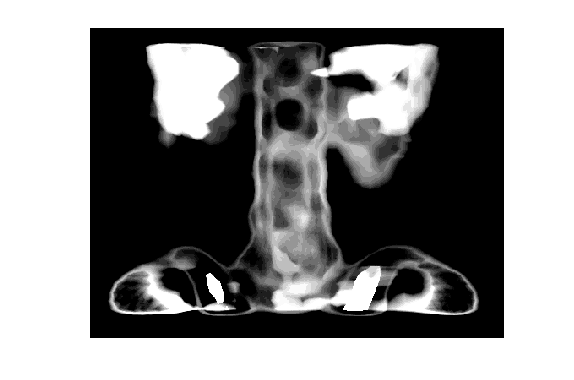

imgadj2 = imadjust(img,[0.1,0.15],[0,1]);
imshow(imgadj2)

# Reshaping a Histogram :

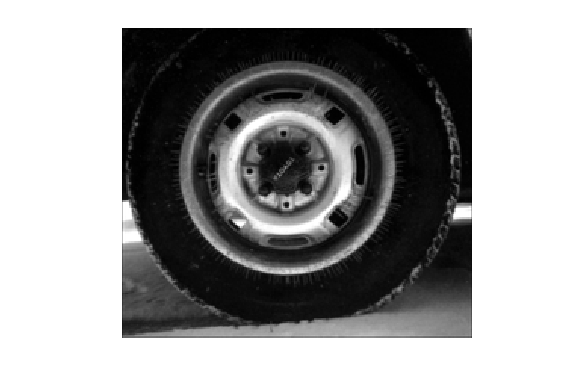

imtire= imread("tire.png");
imshow(imtire)

imgEq = histeq(imtire)

imgEq = 205×232 uint8 matrix
    49   101    73    73    36    28    16    16     4     4    28    36    28    16    16     4     4     0    16    28    16    49    40    16    36     4     4     4    36    28     4    28    16    16     4     0     4     4    36    36     0     4     4     4    16     4     4     4     4     4
    81   113   117   125    49    28    36    36    16    28    40    73    53     4    16    16     4    16     4     4     4    40    40    28    36    16    16    16    28    16    16    28    16    16     4    16    28    16    49    53     4     4    16    28    16    16    16     4    16    36
    81   125   109    73    40    36    36    28    49    53    53    40    16     4     4    16    28    28    16    16    36     0    16    28    16    36    40    36    28    16    28     4     4    16    16    16    28    16    16    16    16    16    16    16    16    16    16    16     4    49
    93   113    49    16    16    16    16    65    81    53     4  

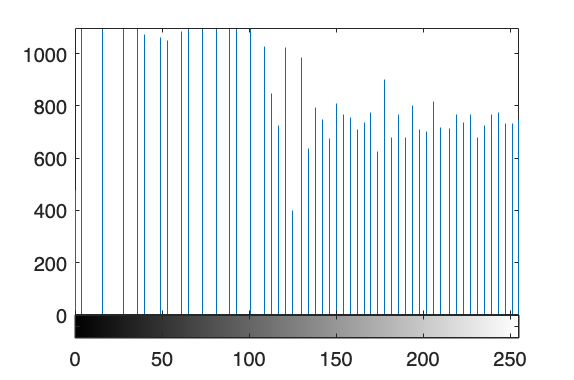

imhist(imgEq)

imgAdj = adapthisteq(imtire)

imgAdj = 205×232 uint8 matrix
    27    56    43    43    20    16    12    12     8     8    16    20    16    12    12     8     8     4    12    16    12    27    24    12    20     8     8     8    20    16     8    16    12    12     8     4     8     8    20    20     4     8     8     8    12     8     8     8     8     8
    47    62    64    69    27    16    20    20    12    16    24    43    31     8    12    12     8    12     8     8     8    24    24    16    20    12    12    12    16    12    12    16    12    12     8    12    16    12    27    31     8     8    12    16    12    12    12     8    12    20
    47    69    58    43    24    20    20    16    27    31    31    24    12     8     8    12    16    16    12    12    20     4    12    16    12    20    24    20    16    12    16     8     8    12    12    12    16    12    12    12    12    12    12    12    12    12    12    12     8    27
    52    62    27    12    12    12    12    39    47    31     8 

montage({imtire, imgAdj})